# Actividad: Separación de minerales

Mateo Minghi - A01711231

F1013

Un campo eléctrico es un campo de fuerza creado por la atracción y repulsión de cargas eléctricas. Por ello, guarda una relación íntima con la Ley de Coulomb.

El campo eléctrico se le puede describir de manera vectorial, ya que tendrá magnitud y dirección. Y, como de costumbre, siempre que se habla de fuerzas resulta pertinente introducir la teoría de Sir. Isaac Newton. 

En este reporte, se modela el movimiento de dos partículas, cuyas características son las mismas, menos la carga. Una será positiva y la otra negativa. Dependiendo de esa única variable, el campo eléctrico cambiará su movimiento.

Primero se establecen las variables del script:

q1 = 10;
q2 = -10;
m = 5; 
E = 500e+3; 
g = 9.81; 

Todos los datos de arriba se mantendrán constantes. Dentro del script, el único dato que varía será el tiempo, por lo que resulta conveniente establerlo como un vector. En este caso, la simulación inicia en un tiempo cero, y termina en un tiempo de 10 segundos:

tiempo_inicial = 0;
tiempo_final = 10; 
t = linspace(tiempo_inicial, tiempo_final, 100); 

Regresando a la teoría, se tiene que pensar en las fuerzas que afectarán el movimiento de la partícula.

En la acelelación vertical (eje Y), se sabe que la gravedad aplica una fuerza hacia abajo, por lo que la aceleración en Y será detonada por: -g.

En la aceleración horizontal (eje X), se sabe que es el capo eléctrico el que aplica la fueza: (q/m)*E

%Aceleración en X
ax_1 = (q1 / m) * E;
ax_2 = (q2 / m) * E;

%Aceleración en Y
ay_1 = -g;
ay_2 = -g;

Para calcular la velocidad, se define una ecuación diferencial que relaciona velocidad con el tiempo. Se resuelve con una integral. El resultado de esa integral propondría una constante de integración. Para conocer su valor, se evalúa el resultado con condiciones iniciales. La velocidad inicial es cero:  

vx(0)=(q/m)*E(0)+C

Por lo tanto, la ecuación para la velocidad en x es: vx=(q/m)*E

Para la velocidad vertical, la lógica es la misma. Ecuación diferencial, integración, evaluación y obtenemos las fórmulas:

%Velocidad en X
vx_1 = (q1 / m) * E * t;
vx_2 = (q2 / m) * E * t;

%Velocidad en Y
vy_1 = (-g .* t);
vy_2 = (-g .* t);


Una vez calculadas las ecuaciones de las velocidades, se integra con la variable de integración del tiempo (dt). Se calcula el valor de la constante de integración y obtenemos las fórmulas de posición:

%Posición en X
x1 = (q1 / (2 * m)) * E * t.^2;
x2 = (q2 / (2 * m)) * E * t.^2;

%Posición en Y
y1 = (-g * t.^2) / 2;
y2 = (-g * t.^2) / 2;


Graficar es muy sencillo, pero veamos por qué las gráficas tienen sentido. 

En la gráfica de posición en X, como la fórmula incluye la carga, y como las cargas son inversas, tiene sentido que su gráfica sea opuesta:

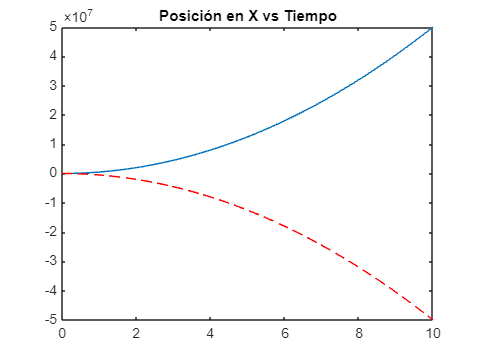

plot(t, x1);
title('Posición en X vs Tiempo');
hold on
plot(t, x2, "--r")
hold off

Como la fórmula de posición en Y no incluye la carga, y las partículas tienen las mismas características, tiene sentido que la gráfica sea la misma:

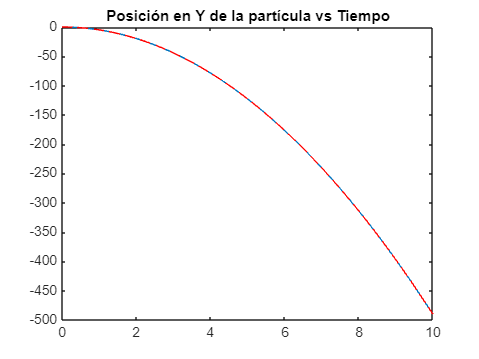

plot(t, y1);
title('Posición en Y de la partícula vs Tiempo');
hold on
plot(t, y2, "--r");
hold off

Como la fórmula de velocidad sí incluye la carga, tiene sentido que sean opuestas:

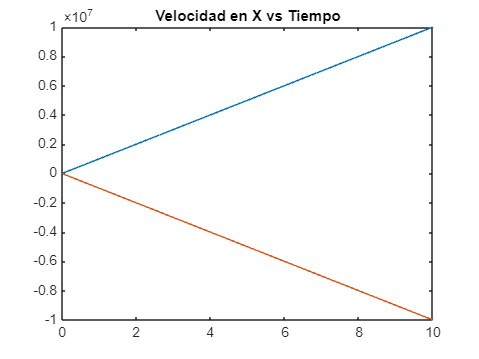

plot(t, vx_1);
title('Velocidad en X vs Tiempo');
hold on
plot(t, vx_2);
hold off

Como la velocidad vertical no incluye la carga, tiene sentido que sea la misma:

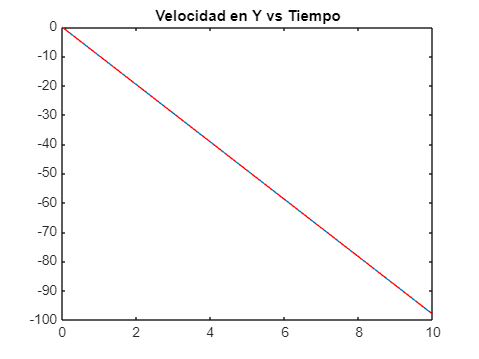


plot(t, vy_1);
title('Velocidad en Y vs Tiempo');
hold on
plot(t, vy_2, "--r");
hold off

Como la aceleración es constante, tiene sentido la forma de la curva. Como sí incluye la carga, tiene sentido que sean opuestas:

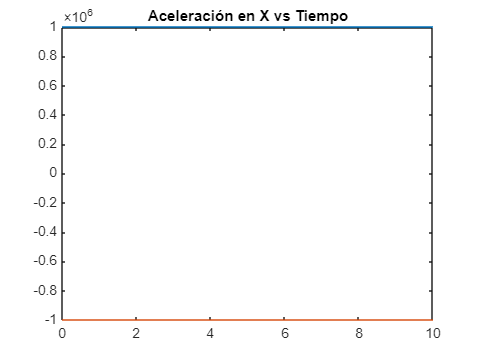

plot(t, ax_1 * ones(size(t)));
title('Aceleración en X vs Tiempo');
hold on
plot(t, ax_2 * ones(size(t)));
hold off

Como la aceleración vertical es constante, y no incluye la carga, tiene sentido que sea la misma

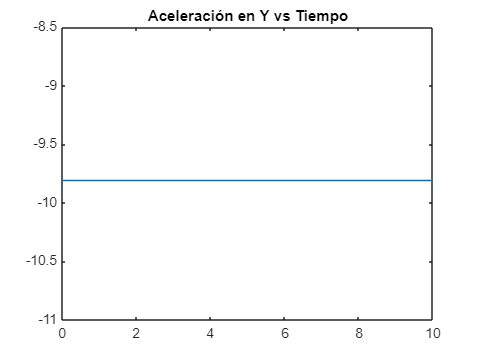

plot(t, ay_1 * ones(size(t)));
title('Aceleración en Y vs Tiempo');